# Performance of naive blocked matrix-matrix multiplication

This Live Script helps you explore how to block for  caches.

You will want to activate the plotting of a new performance curve by changing "( 0 )" to "( 1 )" in the appropriate place.

% load plot colors
my_plot_colors;

% Create figure
figure1 = figure('Name','GFLOPS');

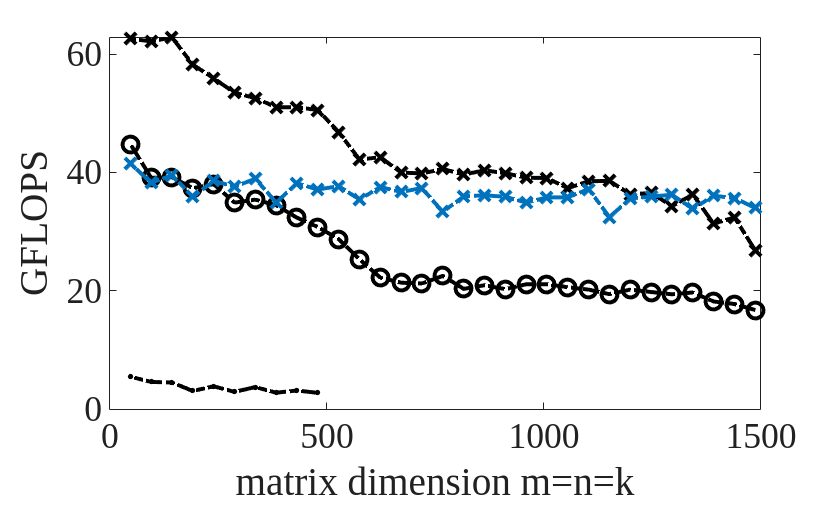


% Create axes, labels, legends.  In future routines for plotting performance, 
% the next few lines will be hidden in the script.
axes2 = axes('Parent',figure1);
hold(axes2,'on');
ylabel( 'GFLOPS', 'FontName', 'Helvetica Neue' );
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );
box(axes2,'on');
set( axes2, 'FontName', 'Helvetica Neue', 'FontSize', 18);

% Plot performance data for IJP loop ordering
if ( 1 )
  system( 'cp ../../../Week1/C/data/output_IJP.m .' );
  output_IJP   % load data
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'IJP', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', '.', 'LineStyle', '-.', 'Color', plot_colors( 1,: ) );
end

% Plot performance data for JI_4x4Kernel
if ( 1 )
  system( 'cp ../../../Week2/C/data/output_JI_4x4Kernel.m .' );
  output_JI_4x4Kernel   % load data
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_4x4Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 1,: ) );
end

% Plot performance data for JI_12x4Kernel
if ( 1 )
  system( 'cp ../../../Week2/C/data/output_JI_12x4Kernel.m .' );
  output_JI_12x4Kernel   % load data
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_12x4Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', 'x', 'LineStyle', '-.', 'Color', plot_colors( 1,: ) );
end

% Plot time data for IJP_JI_4x4Kernel (to plot change "0" to "1")
if ( 1 ) 
  output_IJP_JI_4x4Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'IJP\_JI\_4x4Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'x', 'LineStyle', '-.', 'Color', plot_colors( 2,: ) );
end


% Plot time data for IJP_JI_12x4Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_IJP_JI_12x4Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'IJP\_JI\_12x4Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'x', 'LineStyle', '-', 'Color', plot_colors( 3,: ) );
end

% Plot time data for IPJ_JI_12x4Kernel (to plot change "0" to "1")
if ( 0 ) 
  output_IPJ_JI_12x4Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'IPJ\_JI\_12x4Kernel', 'MarkerSize', 8, 'LineWidth', 3, ...
        'Marker', 'x', 'LineStyle', '-', 'Color', plot_colors( 4,: ) );
end

% Plot time data for JIP_JI_12x4Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JIP_JI_12x4Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JIP\_JI\_12x4Kernel', 'MarkerSize', 8, 'LineWidth', 3, ...
        'Marker', 'x', 'LineStyle', '--', 'Color', plot_colors( 5,: ) );
end

% Plot time data for JPI_JI_12x4Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JPI_JI_12x4Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JPI\_JI\_12x4Kernel', 'MarkerSize', 8, 'LineWidth', 3, ...
        'Marker', 'x', 'LineStyle', '-', 'Color', plot_colors( 6,: ) );
end

% Plot time data for PIJ_JI_12x4Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_PIJ_JI_12x4Kernel 
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'PIJ\_JI\_12x4Kernel ', 'MarkerSize', 8, 'LineWidth', 3, ...
        'Marker', '*', 'LineStyle', '--', 'Color', plot_colors( 1,: ) );
end

Unrecognized function or variable 'output_PIJ_JI_12x4Kernel'.


% Plot time data for PJI_JI_12x4Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_PJI_JI_12x4Kernel 
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'PJI\_JI\_12x4Kernel ', 'MarkerSize', 8, 'LineWidth', 3, ...
        'Marker', '*', 'LineStyle', '-', 'Color', plot_colors( 2,: ) );
end


% Optionally show the reference implementation performance data
if ( 1 )
  plot( data(:,1), data(:,3), 'MarkerSize', 8, 'LineWidth', 1, ...
        'LineStyle', '-', 'DisplayName', 'Ref', 'Color', plot_colors( 1,: ) );
end

% Adjust the x-axis and y-axis range to start at 0
v = axis;                   % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )   % start the x axis and y axis at zero

% Optionally change the top of the graph to capture the theoretical peak
if ( 0 )
    turbo_clock_rate = 4.3;
    flops_per_cycle = 16;
    peak_gflops = turbo_clock_rate * flops_per_cycle;

    axis( [ 0 v(2) 0 peak_gflops ] )  
end

legend2 = legend( axes2, 'show' );
set( legend2, 'Location', 'southwest', 'FontSize', 14) ;

% Uncomment if you want to create a pdf for the graph
print( 'Plot_XYZ_JI_MRxNR.png', '-dpng' );